clear all, close all, clc;

% Import data from text file
% Script for importing data from the following text file:
%
%    filename: observerComparism2.csv
%
% Auto-generated by MATLAB on 13-Apr-2023 18:01:37

## Constants

FIRST_SAMPLE_IDX = 1000;
LAST_SAMPLE_IDX = 20000;
CAM_DELAY_IN_CYCLES = 61;
CORRELATION_WINDOW_WIDTH = 5000;
CORRELATION_MAX_DELAY = 1000;
%Kreisfahrt 103.3864ms  Sinusfahrt 160.3870ms   WallCrash 106ms --> Mean
%123.2578ms (61cycles) (cycle time: 2 ms)

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 5, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = [FIRST_SAMPLE_IDX, LAST_SAMPLE_IDX];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["t", "yObs", "yRef", "yCam", "yKalman"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
tbl = readtable("FUN-VPJ2.csv", opts);

% Convert to output type
t = tbl.t / 1000;       % ms -> s
t = t - t(1);           % ensure t(0) = 0 s
xObs = tbl.yObs;
xRef = tbl.yRef;
xCam = tbl.yCam;
xKalman = tbl.yKalman;

% Clear temporary variables
clear opts tbl

% Clean cam data from zeros and linear interpolation
xCam = filloutliers(xCam, "linear", "movmedian", 1500, "ThresholdFactor",2.25);

% Shift data to obtain "real" position values
xReal = xCam(CAM_DELAY_IN_CYCLES + 1 : end);
xCam = xCam(1 : end - CAM_DELAY_IN_CYCLES);
xRef = xRef(1 : end - CAM_DELAY_IN_CYCLES);
xObs = xObs(1 : end - CAM_DELAY_IN_CYCLES);
xKalman = xKalman(1 : end - CAM_DELAY_IN_CYCLES);
t = t(1 : end - CAM_DELAY_IN_CYCLES);



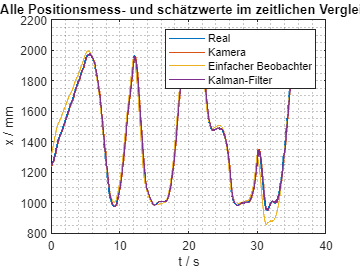

plot(t, xReal, t, xCam, t, xObs, t, xKalman);
grid minor;
legend('Real', 'Kamera', 'Einfacher Beobachter', 'Kalman-Filter');
xlabel("t / s"), ylabel("x / mm");
title("Alle Positionsmess- und schätzwerte im zeitlichen Vergleich")

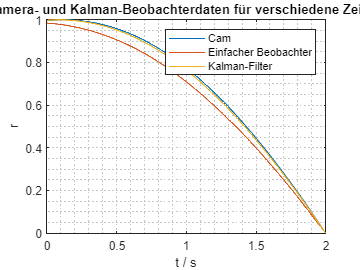



% Korrelationen
seObs = zeros(1000, CORRELATION_WINDOW_WIDTH);
sseObs = zeros(1, 1000);
seKalman = zeros(1000, CORRELATION_WINDOW_WIDTH);
sseKalman = zeros(1, 1000);
seCam = zeros(1000, CORRELATION_WINDOW_WIDTH);
sseCam = zeros(1, 1000);
seReal = zeros(1000, CORRELATION_WINDOW_WIDTH);
sseReal = zeros(1, 1000);

for delay = [1 : CORRELATION_MAX_DELAY]
    seCam(delay, :) = ((xReal(1 : CORRELATION_WINDOW_WIDTH) - xCam(delay : delay + CORRELATION_WINDOW_WIDTH - 1)).^2)';
    sseCam(delay) = sum(seCam(delay, :));
    seObs(delay, :) = ((xReal(1 : CORRELATION_WINDOW_WIDTH) - xObs(delay : delay + CORRELATION_WINDOW_WIDTH - 1)).^2)';
    sseObs(delay) = sum(seObs(delay, :));
    seKalman(delay, :) = ((xReal(1 : CORRELATION_WINDOW_WIDTH) - xKalman(delay : delay + CORRELATION_WINDOW_WIDTH - 1)).^2)';
    sseKalman(delay) = sum(seKalman(delay, :));
end

sseReal = sseReal / max(sseReal);
rReal = 1 - sseReal;
sseCam = sseCam / max(sseCam);
rCam = 1 - sseCam;
sseObs = sseObs / max(sseObs);
rObs = 1 - sseObs;
sseKalman = sseKalman / max(sseKalman);
rKalman = 1 - sseKalman;

tCorr = t(1:CORRELATION_MAX_DELAY);
plot(tCorr, rCam, tCorr, rObs, tCorr, rKalman)
grid minor
xlabel("t / s"), ylabel("r")
title("Korrelation von Kamera- und Kalman-Beobachterdaten für verschiedene Zeitverzögerungswerte")
legend("Cam", "Einfacher Beobachter", "Kalman-Filter")


[rMaxKalman, delayInCyclesKalman] = max(rKalman);
[rMaxObs, delayInCyclesObs] = max(rObs);

delayInMsKalman = delayInCyclesKalman * 2;
delayInMsObs = delayInCyclesObs * 2;
